# Stochastic gradient descent

In this demo, we will compare classical gradient descent with stochastic gradient descent. We'll generate synthetic data and try to estimate the parameters of a straight line, $y=x+1$, i.e., the parameters are $w_0=1$ and $w_1=1$. The estimates will be found by minimizing the residual sum of squares.

### Data without noise

First we'll generate some data without noise.

global x y
n = 10;
x = (0:1/(n-1):1)';
y = x+1;

Construct an initial guess for the optimization procedures. The expect values of the initial guesses are $w_0=1$ and $w_1=1$.

rng(0); % comment this out to try other initial guesses
w0_init = 6*rand-2;
w1_init = 6*rand-2;

The residual sum of squares error function is defined below. Plot contours of the error function. Also plot the initial guess.

clf; fcontour(@E, [-2 4 -2 4],'LevelList',[0:1:30],'MeshDensity',200); hold on
plot(w0_init, w1_init, 'o', 'markerfacecolor', 'k');

Call gradient descent and stochastic gradient descent. Use 10 epochs and a learning rate (step size) of 0.06 for gradient descent.

 gd(w0_init, w1_init, x, y, 10, 0.06);

 GD final error: 1.628058e-01


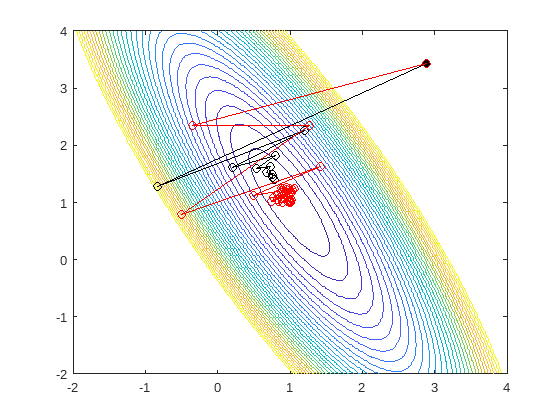

SGD final error: 1.189290e-14


sgd(w0_init, w1_init, x, y, 10, 0.06*n, 1.);

### Data with noise

Now we'll generate `y` values with noise.

y = x+1 + 0.1*randn(size(x));

Draw the contours and the results using gradient descent and stochastic gradient descent. The learning rates are the same as above.

clf; fcontour(@E, [-2 4 -2 4],'LevelList',[0:1:30],'MeshDensity',200); hold on
plot(w0_init, w1_init, 'o', 'markerfacecolor', 'k');
 gd(w0_init, w1_init, x, y, 10, 0.06);

 GD final error: 2.586503e-01


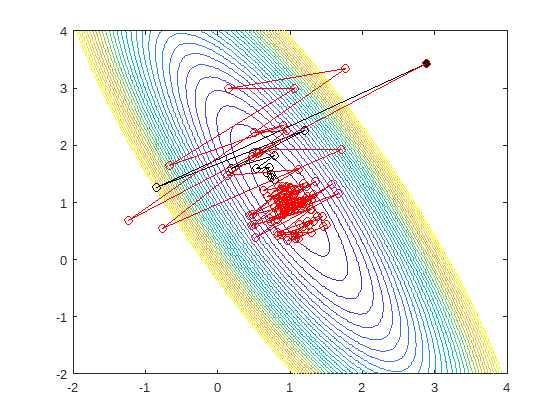

SGD final error: 2.741891e-01


sgd(w0_init, w1_init, x, y, 10, 0.06*n, 1.);

Repeat the above experiment, but this time we'll decrease the learning rate by a factor of 1.5 after every epoch.

clf; fcontour(@E, [-2 4 -2 4],'LevelList',[0:1:30],'MeshDensity',200); hold on
plot(w0_init, w1_init, 'o', 'markerfacecolor', 'k');
 gd(w0_init, w1_init, x, y, 10, 0.06);

 GD final error: 2.586503e-01


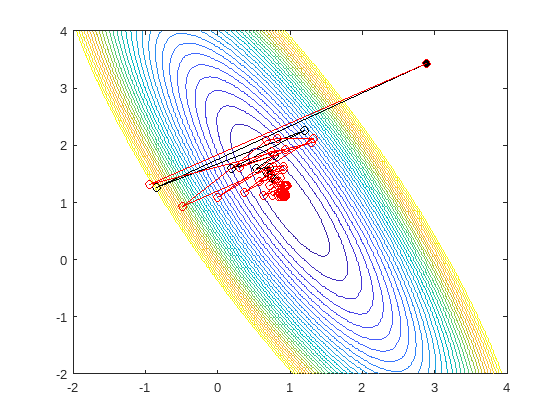

SGD final error: 1.097839e-01


sgd(w0_init, w1_init, x, y, 10, 0.06*n, 1.5);

Here are the functions for gradient descent, stochastic gradient descent, and the error function.

function gd(w0, w1, x, y, nepochs, eta)
for k = 1:nepochs
  dw0 = sum(2*(w0+w1*x-y));
  dw1 = sum(2*(w0+w1*x-y).*x);
  plot([w0 w0 - eta*dw0],[w1 w1 - eta*dw1],'k-o');
  w0 = w0 - eta*dw0;
  w1 = w1 - eta*dw1;
end
fprintf(' GD final error: %e\n', E(w0,w1));
end

function sgd(w0, w1, x, y, nepochs, eta, etafac)
for k = 1:nepochs
  p = randperm(length(x));
  for j = 1:length(x)
    dw0 = sum(2*(w0+w1*x(p(j))-y(p(j))));
    dw1 = sum(2*(w0+w1*x(p(j))-y(p(j))).*x(p(j)));
    plot([w0 w0 - eta*dw0],[w1 w1 - eta*dw1],'r-o');
    w0 = w0 - eta*dw0;
    w1 = w1 - eta*dw1;
  end
  eta = eta/etafac;
end
fprintf('SGD final error: %e\n', E(w0,w1));
end

% error function
function val = E(w0,w1)
global x y
val = 0;
for i = 1:length(x)
  val = val + (w0+w1*x(i)-y(i)).^2;
end
end
